
Parameter Set 1:


True B coefficients:


    0.5000    0.3000



Estimated B coefficients from OE model:


    0.9802
   -0.1485



Estimated B coefficients from ARX model:


    0.5694
    0.8109



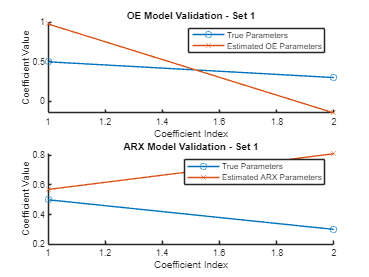


Parameter Set 2:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.1570
   -0.1629



Estimated B coefficients from ARX model:


    0.5960
    0.2847



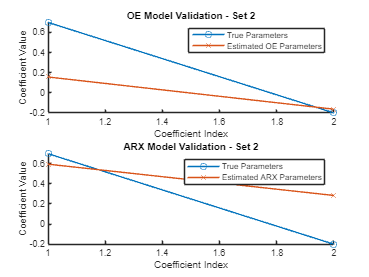


Parameter Set 3:


True B coefficients:


    0.6000    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.0516
    0.8072
    0.5452



Estimated B coefficients from ARX model:


   1.0e+28 *

   -1.4855
   -0.9904
   -0.9904



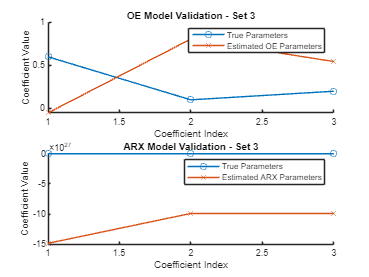

%  multiple sets of true system parameters
param_sets = {
    struct('B_true', [0.5, 0.3], 'A_true', [1, -1.2, 0.36]),
    struct('B_true', [0.7, -0.2], 'A_true', [1, -0.8, 0.48]),
    struct('B_true', [0.6, 0.1, 0.2], 'A_true', [1, -1.5, 0.7, -0.3])
};

N = 1000;  % data points
noise_variance = 5;

% set of system parameters
for i = 1:length(param_sets)
    B_true = param_sets{i}.B_true;
    A_true = param_sets{i}.A_true;
    nk = 1;  % Assuming a constant delay for simplicity

    % Generate input data
    u = randn(N, 1);

    % Generate noise-free system output using the current true parameters
    y_true = filter([0, B_true], A_true, u);

    % Add white noise to the output
    noise = sqrt(noise_variance) * randn(N, 1);
    y_noisy = y_true + noise;

    % Fit models
    nb = length(B_true);  % Number of B coefficients
    nf = length(A_true) - 1;  % Number of F coefficients in OE model

    oe_model = oefit([y_noisy, u], [nb, nf, nk]);
    arx_model = arxfit([y_noisy, u], [nf, nb, nk]);

    % Display results
    fprintf('\nParameter Set %d:\n', i);
    disp('True B coefficients:');
    disp(B_true);
    disp('Estimated B coefficients from OE model:');
    disp(oe_model.B);
    disp('Estimated B coefficients from ARX model:');
    disp(arx_model.B);

    % Plotting results
    figure;
    subplot(2,1,1);
    hold on;
    plot(B_true, 'o-', 'DisplayName', 'True Parameters');
    plot(oe_model.B, 'x-', 'DisplayName', 'Estimated OE Parameters');
    title(sprintf('OE Model Validation - Set %d', i));
    legend;
    xlabel('Coefficient Index');
    ylabel('Coefficient Value');
    hold off;

    subplot(2,1,2);
    hold on;
    plot(B_true, 'o-', 'DisplayName', 'True Parameters');
    plot(arx_model.B, 'x-', 'DisplayName', 'Estimated ARX Parameters');
    title(sprintf('ARX Model Validation - Set %d', i));
    legend;
    xlabel('Coefficient Index');
    ylabel('Coefficient Value');
    hold off;
end